# **VAJE 5**

H1(z) = ((1-z^(-m))/(1-z^(-1)))^M => m nicel, tista pri x=1 y=0 se iznici

H2(z) = (1+ Ck*z^(-i))^N

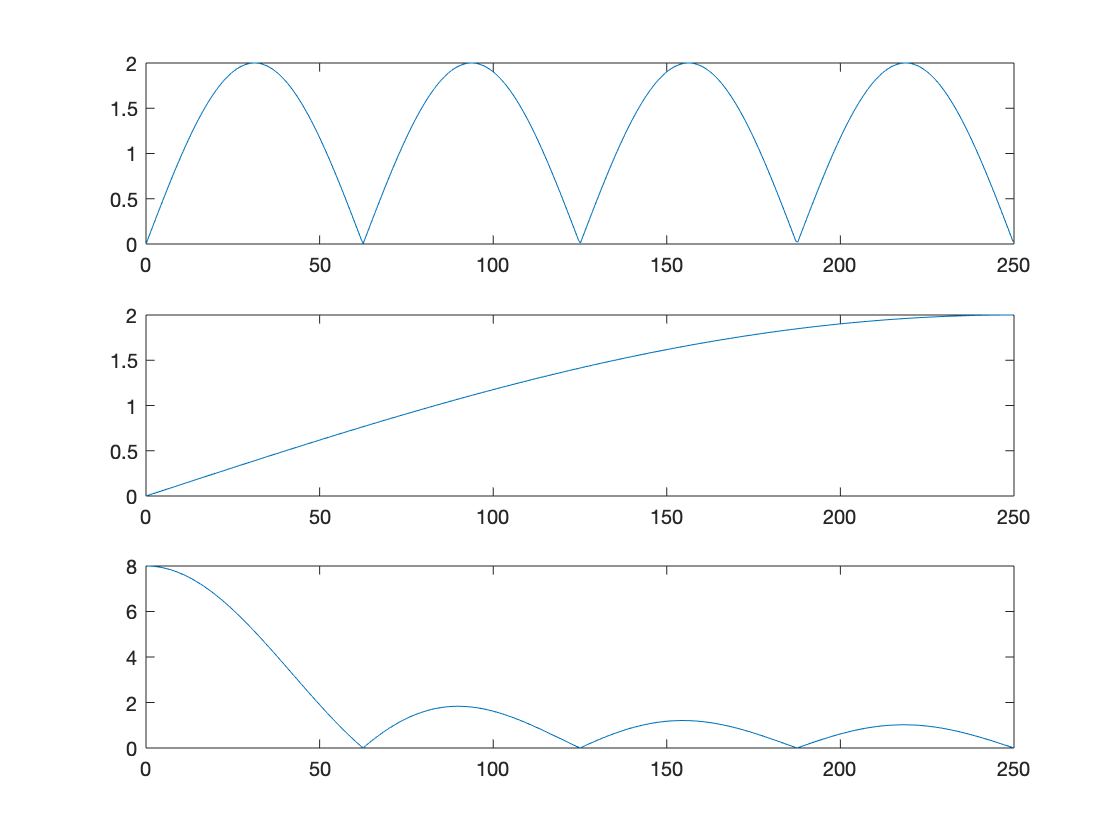

transferCharacteristic1(8,1); figure;

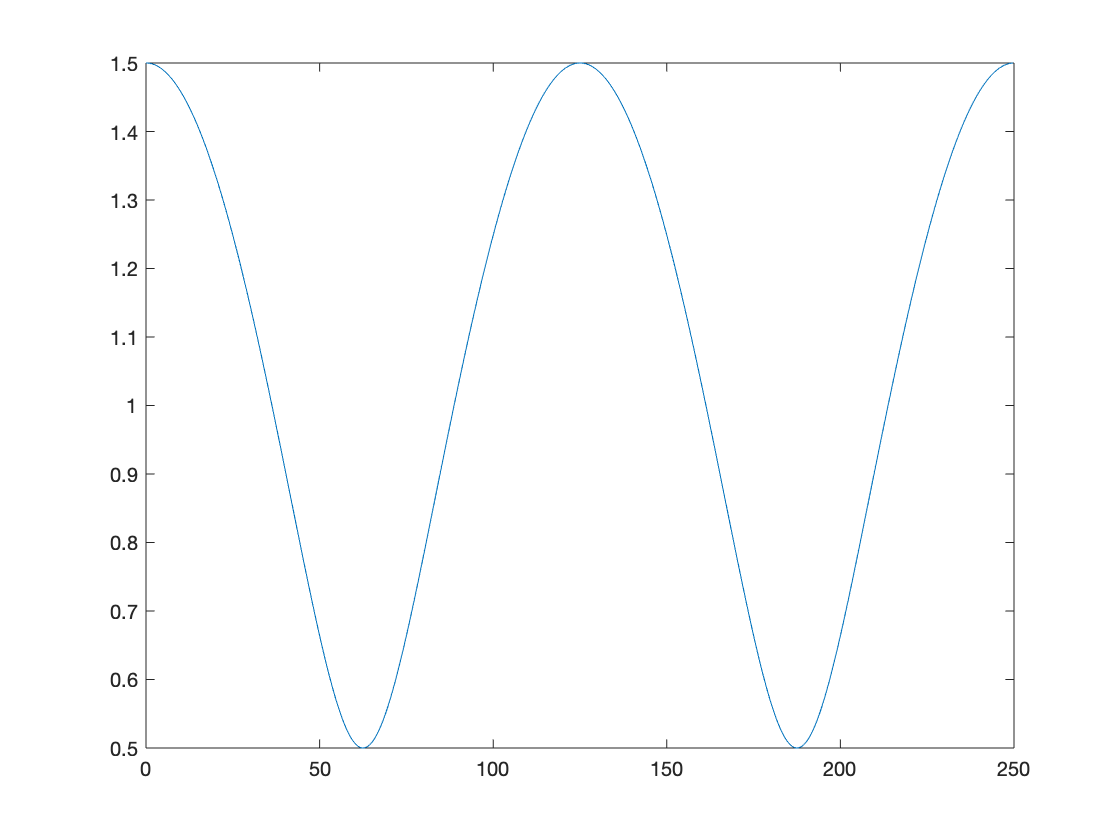

transferCharacteristic2(0.5,4,1); figure;

H3(z) = H1(z) * (1/H2(z))

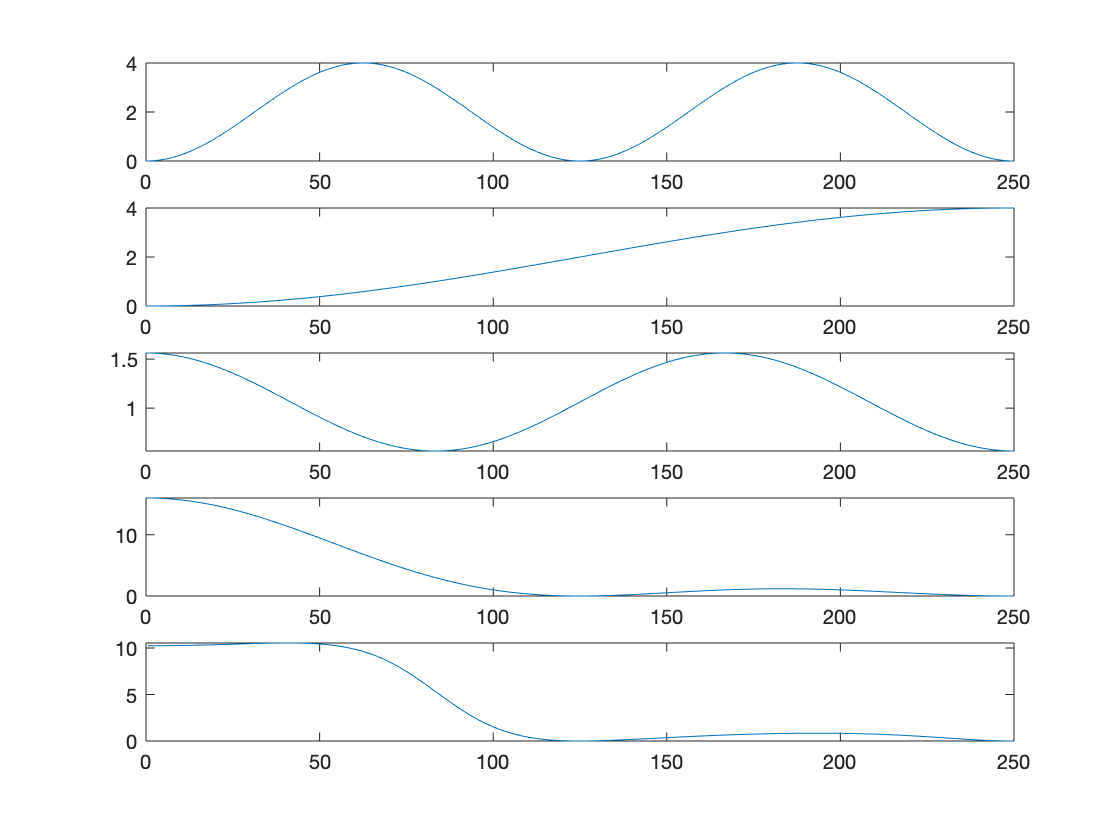

transferCharacteristic3 (0.25,3,2,4,2); figure;

H4(z) = (1 + Ak*z^(-m))^M/(1 + Bk*z^(-n))^N = (H4a(z))/(H4b(z));  m=k*n zato da se poli in nicle pokrajsajo; k=z; k>0

Prepusca ravno frekvence, ki se jih hocemo znebit

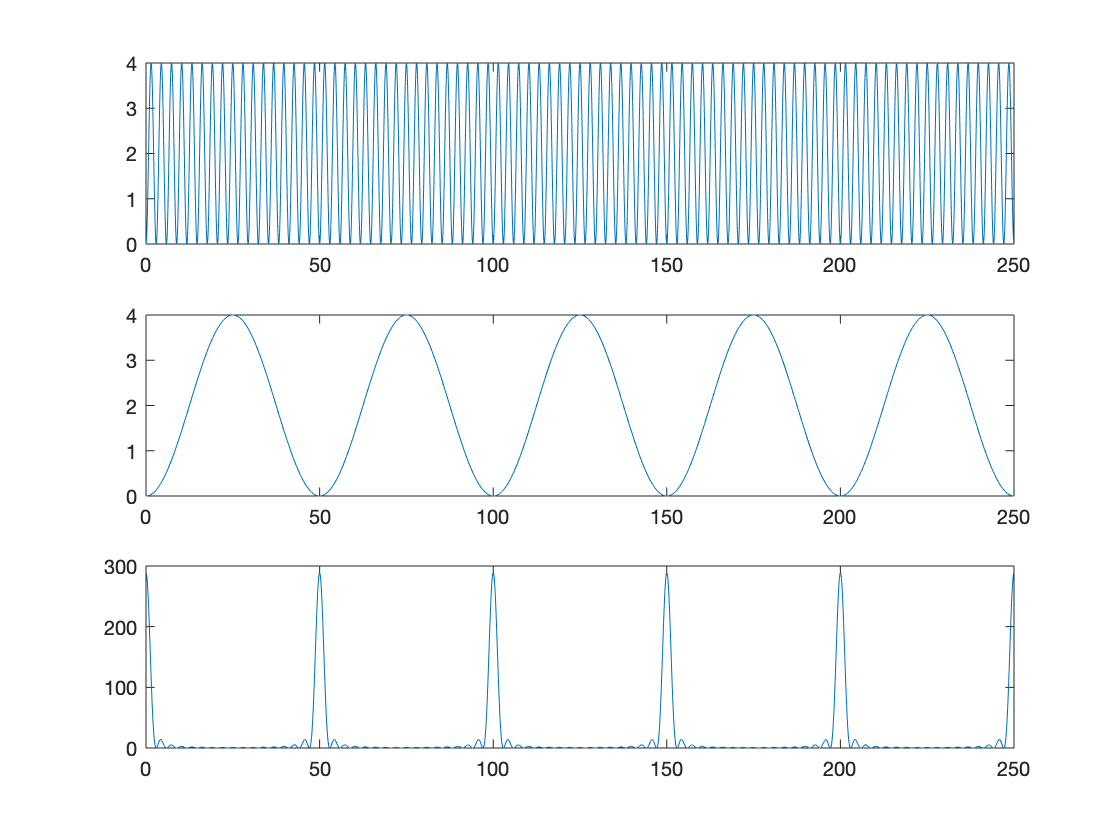

transferCharacteristic4(-1,-1,170,10,2,2); figure;

H5(z) = z^(-D) - H4(z)/G; G = (m/n)*M; D = ((m-n)/2)*M

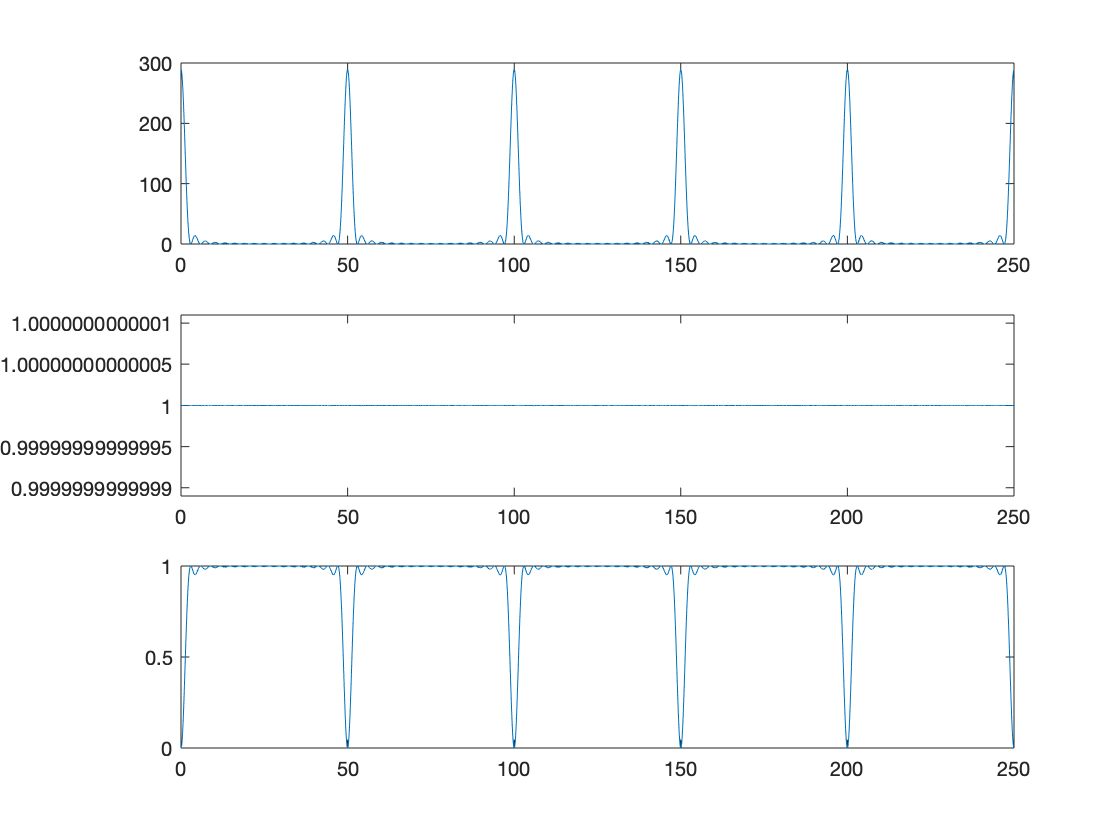

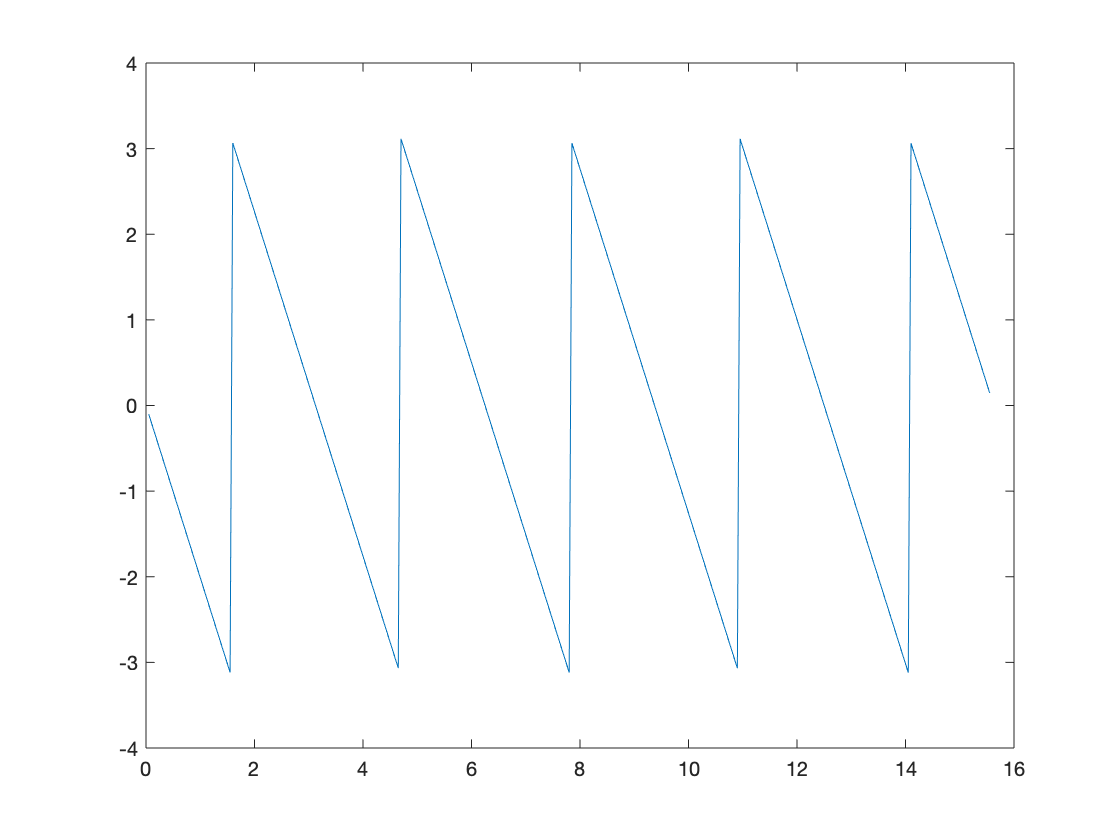

transferCharacteristic5(-1,-1,170,10,2,2); figure;

500 Hz/10 = 50 Hz, zato dobimo pri 50 nicle

FIR 

-  y(n) = sum {m=0; M-1; Bm*x*(n-m)}, kako izracunat b-je?

b = fir1(M, Fc, 'high'); Fc = 0...1, 0 = 0 Hz, 1= FFs/2 (Fs := small letter with index, FFs := Capital letter with index)

S tem odstranjujemo nizke signale in tako nihanje baselina

Fs = 250;
Fc = 0.8;
fc = Fc / (Fs/2);
n = 100;
b = fir1 (n, fc, 'high')

b =    -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0019   -0.0021   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0031   -0.0033   -0.0035   -0.0037   -0.0039   -0.0041   -0.0043   -0.0044   -0.0046   -0.0048   -0.0049   -0.0051   -0.0053   -0.0054   -0.0056   -0.0057   -0.0058   -0.0059   -0.0060   -0.0061   -0.0062   -0.0062   -0.0063   -0.0063   -0.0064   -0.0064


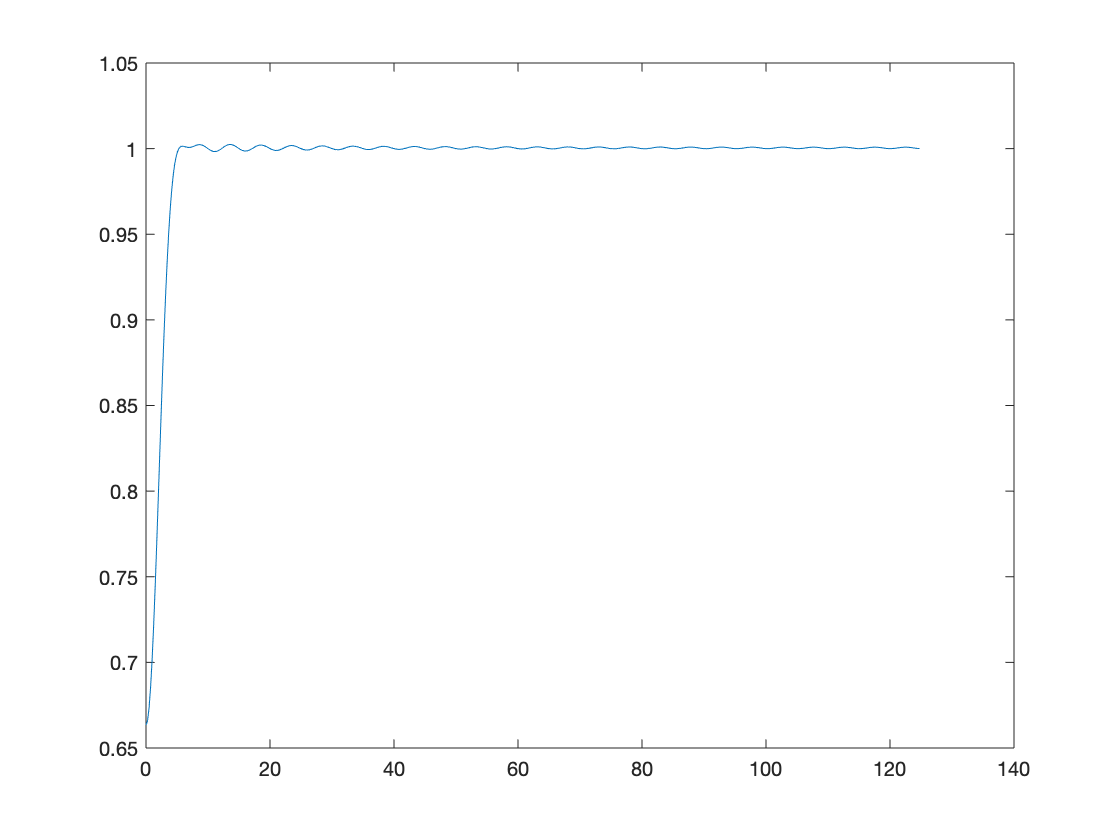

[h, w] = freqz(b,1);
plot(w/(2*pi)*Fs, abs(h));

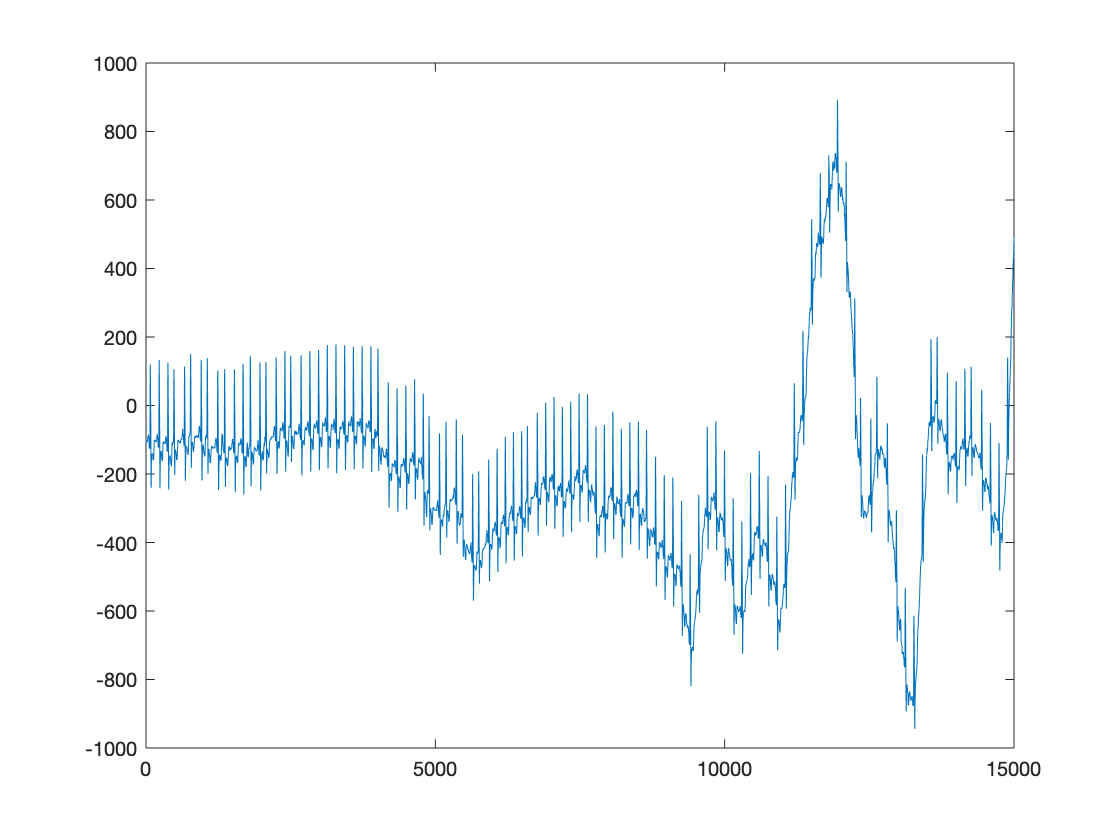

load ('s20501m.mat');
sig = val(2,:);
plot(sig);

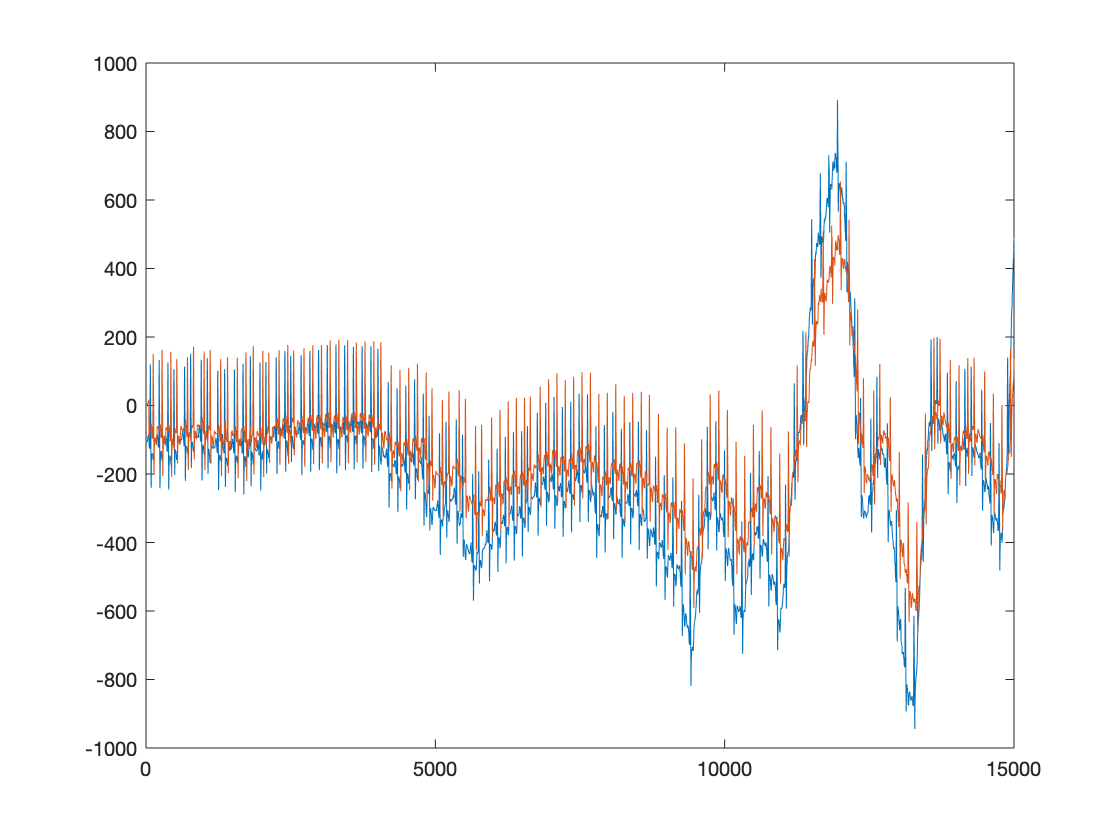

fsig = filter(b,1,sig);
plot(sig); hold on; plot(fsig);

% klici evalfir iz command windowa (uporablja sig)